clear all; 
close all; 
clc; 
warning off;

## read image

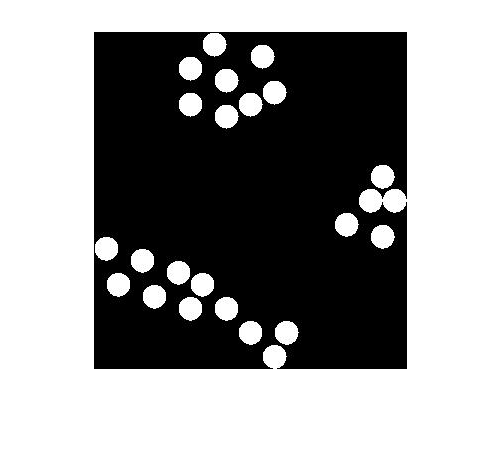

inputImg = imread('testImg.jpg');
figure(1), imshow(inputImg);
saveas (figure(1), 'img.pdf');

## count the connected components.

bw = im2bw(inputImg); %% binay conversion.
cc = bwconncomp(bw);
disp(['No. of connected components : ' num2str(cc.NumObjects)]);

No. of connected components : 23


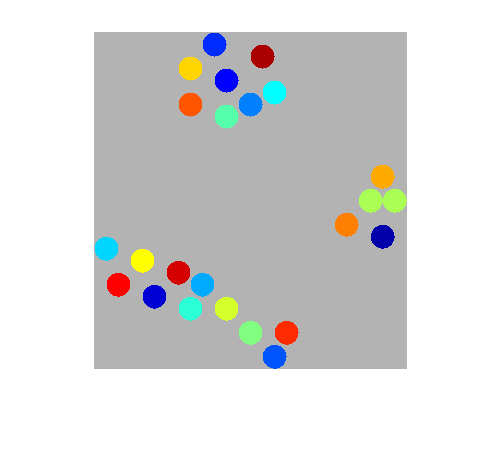

L = labelmatrix(cc);
rgb = label2rgb(L, 'jet', [.7 .7 .7], 'shuffle');
figure(2), imshow(rgb) % visualize how many are they.
saveas (figure(2), 'img_label.pdf');

## connect objects using distance transform

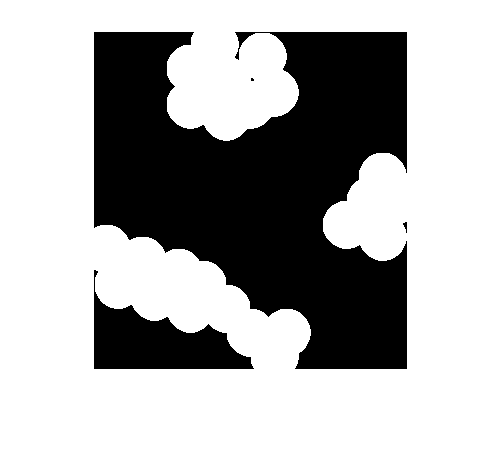

bw2 = bwdist(bw) <= 12.5; % connect objects that are 25 pixels far from each other.
figure(3), imshow(bw2); 
saveas (figure(3), 'imgBW.pdf');

## label them again.

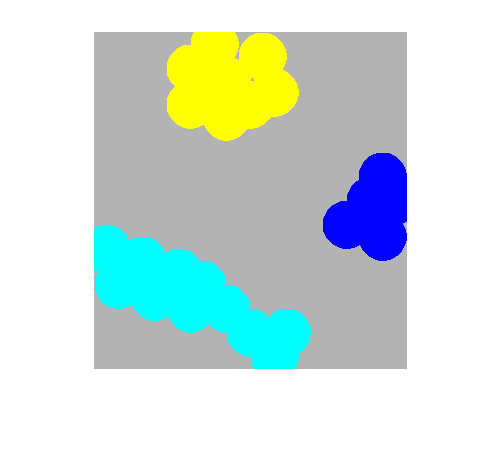

L2 = labelmatrix(bwconncomp(bw2));
rgb2 = label2rgb(L2, 'jet', [.7 .7 .7], 'shuffle');
figure(4), imshow(rgb2);
saveas (figure(4), 'imgBW_label.pdf');

## take those objects that formed the cluster

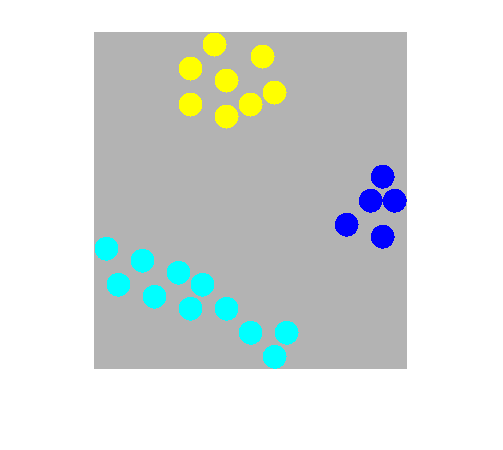

L2(~bw) = 0;
figure(5), imshow(label2rgb(L2, 'jet', [.7 .7 .7], 'shuffle'))
saveas (figure(5), 'img_label_cluster.pdf');